434 HW 2 Isaac Shelby 

1) A little introductory brain teaser. Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice  sum to seven)? What is the ratio of the probabilities? 

There is only one way to roll a 2 with two die: both are ones. There are six ways to roll a 7: 1 and 6, 2 and 5, 3 and 4 (two ways for each of these with the two die). As each die has 6 possible outcomes, there are 36 total outcomes for rolling the 2 dice. Thus, the probability of rolling a 2 when rolling 2 six-sided dice is 1/36, whereas the probability of rolling a 7 is 6/36 or 1/6. The probability of rolling a 7 is 6 times as likely as rolling a 2.

2)  Following what we did in class show how to use the convolution operator to determine the probability of the **sum** of 2 six sided dice. Do both analytically (math & counting) and numerically (computer program). Beware the *implicit* definition of the values (x-axis on histogram).

We have already begun the process of determining the pdf for the sum of rolling two die and we can continue to do so below. Following the method of convolution, we can think of sliding the two numberlines 1-6 and 6-1 past each other. Starting with just 1 and 1 overlapping, and continuing by one jump at a time, we can see that the sum of all pairs remains fixed. Similarly, by sliding them past each other by one space, the sum only increases or decreases by one. This starting with 1/36 probability (1/6*1/6) for a sum of 2, the probability increases by 1/36 up to a maximum of 6/36 (for a sum of 7) when the numberlines completely overlap. Then they decrease by 1/36 at a time.

P(2) = 1/36, P(3) = 2/36, P(4) = 3/36, P(5) = 4/36, P(6) = 5/36, P(7) = 6/36, P(8) = 5/36, P(9) = 4/36, P(10) = 3/36, P(11) = 2/36, P(12) = 1/36.  

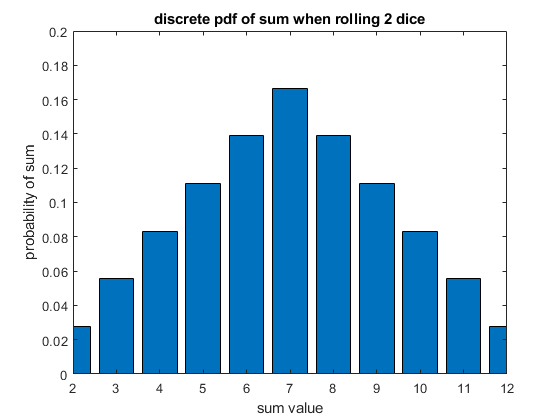

die_min = 1;
die_max = 6;

die_vals = die_min:die_max;
die_probs = unidpdf(die_vals, die_max);

sum_min = 2*die_min;
sum_max = 2*die_max;
sum_vals = sum_min:sum_max;
prob_of_sum = conv(die_probs, die_probs);

figure(1)
bar(sum_vals,prob_of_sum)
title('discrete pdf of sum when rolling 2 dice')
ylabel('probability of sum')
xlabel('sum value')
ylim([0,0.2]);
xlim([2,12])

3) Calculate the mean and the variance of the distribution in problem 2.  Hint: this is surprisingly tricky, make sure your result makes sense.

Mean of a discrete variable $X$ with proability function $P(X)$ is defined as the sum over all possible values of $X$, $\{x_i \}$,  weighted by their respective probabilities: $\mathbb{E}(X) = \sum_{x_i} x_i \times P(X = x_i)$. 

mean_of_sum_of_two_die = dot(prob_of_sum, sum_vals)

mean_of_sum_of_two_die = 7

The variance of a discrete variable $X$ is defined as the difference in the mean of the variable squared minus the square of the mean of the variable: $\text{Var}(X) = \mathbb{E}(X^2) - \mathbb{E}(X)^2 = \sum_{x_i} x_i ^2 \times P(X = x_i) - \left(\sum_{x_i} x_i \times P(X = x_i) \right)^2$

expectation_of_sum_squared = dot(prob_of_sum, sum_vals.^2);
variance_of_sum_of_two_die = expectation_of_sum_squared - mean_of_sum_of_two_die^2

variance_of_sum_of_two_die = 5.8333

4) Repeat 2, and graph the **average** of 10 dice. Is this is a Gaussian distribution? Explain in depth. 

The pdf for the average of 10 dice is *nearly* identical to the pdf for the sum of 10 dice. The probability distribution has the same shape, but by dividing out the values by 10 to obtain the average, it shrinks the width of the distribution:

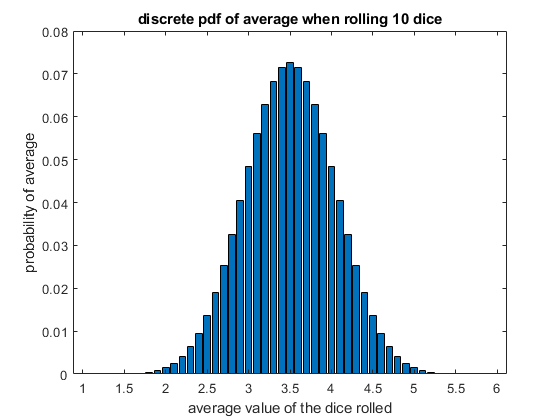

number_of_dice = 10;

for i = 1:number_of_dice
    if i == 1
        pdf_of_sum = die_probs;
    else
        temp = conv(pdf_of_sum, die_probs);
        pdf_of_sum = temp;
    end
end

n_sum_min = number_of_dice*die_min;
n_sum_max = number_of_dice*die_max;

n_sum_vals = n_sum_min:n_sum_max;
n_avg_vals = n_sum_vals / number_of_dice;

figure(2)
bar(n_avg_vals, pdf_of_sum)

title(['discrete pdf of average when rolling ' num2str(number_of_dice)  ' dice'])
ylabel('probability of average')
xlabel('average value of the dice rolled')

This looks very much like a Gaussian distribution. The central limit theorem states that taking the average of $n$ random samples pulled from identical distributions with the same mean and finite variance, the limiting form of the distribution is the standard normal distribution (https://en.wikipedia.org/wiki/Central_limit_theorem). So, in one way it is like the normal distribution. But, this is still a discrete distribution, we haven't yet taken the number of dice that we are averaging together towards infinity. And in a real experiment, with a finite number of measurements, the distribution will always remain discrete. So while the discrete values of the distribution will approach values equivalent to evaluating a normal distribution at those points, it will still be a discrete distribution. Below, we plot the discrete distribution and limiting distribution on the same axes. The limiting distribution has mean of 3.5 and variance of $2.9167 / n$. (The 2.9167 comes from the variance of a single die, calculated below as well). Note that we carefull choose to bin the analytic normal distribution we are plotting with the same number of bins as the discrete distribution has. This would be less necessary when looking at a cdf, but pdf values are more sensitive to the width you assign each value. We see good agreement in the center of the distribution, with increasing error towards the tails. 

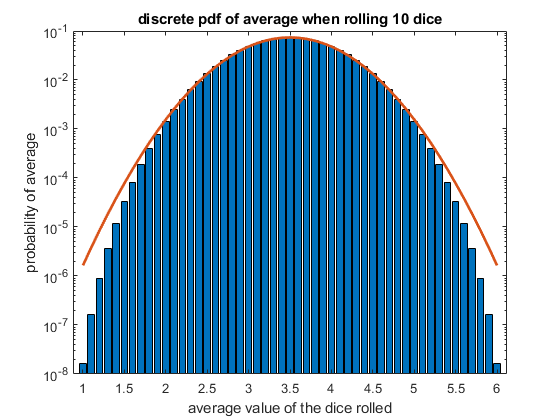

single_die_mean = dot(die_vals, die_probs);
single_die_variance = dot(die_vals.^2, die_probs) - dot(die_vals, die_probs)^2;

limiting_distribution = makedist("Normal","mu",single_die_mean,"sigma",sqrt(single_die_variance / number_of_dice));
x = linspace(1, 6, (die_max-1)*number_of_dice + 1 );
limiting_pdf = pdf(limiting_distribution,x);
limiting_pdf = limiting_pdf / sum(limiting_pdf);

figure(2)
bar(n_avg_vals, pdf_of_sum)
hold on

title(['discrete pdf of average when rolling ' num2str(number_of_dice)  ' dice'])
ylabel('log probability of average')
xlabel('average value of the dice rolled')
plot(x,limiting_pdf,"LineWidth",2);
set(gca,'YScale','log')

 5) Show that the sum and average of an initially Gaussian distribution is  also a Guassian (can be analytic or numerical). How does the standard  deviation of the resulting sum or average Guassian change? This is a *hugely* important result. Explore what this means for integrating a signal over time. 

As mentioned earlier, the average of a series of measurements has a nearly identical pdf to the sum of a series of measurement. The sole difference being the average is compressed along the x-axis when dividing the sum of all the measurements by the number of measurements to get the average. As a consequence, if the sum of two Gaussian distributed variables is another Gaussian disributed variable, the mean of two is as well, albeit with different mean and standard deviation than the sum.  Specifically, the mean of the average is equivalent to the mean of the sum divided by 2 (as we are only summing two variables to begin), and the standard deviation of the average is the standard deviation of the sum divided by 2 as well. All this to say that if the sum of two Gaussian distributions is Gaussian, so is the average of two Gaussian variables. Going a step further, if the sum of 2 Gaussian variables is Gaussian, so is the sum of any number of Gaussian variables. This can be seen by thinking of grouping the first two variables in the sum and replacing them with the Gaussian variable that describes their sum. Repeating this step with the new first two terms in the sum allows for the whole sum to be expressed as a single Gaussian variable. This then implies that the same can be done for averaging many Gaussian variables. Some care is required here if doing this piecewise, as it will require computing weighted averages. All of this is conditional on the variables being independent. According to wikipedia (https://en.wikipedia.org/wiki/Sum_of_normally_distributed_random_variables), this condition can be weakened in special cases, but we will stick to the case of the variables being independent. Below we closely follow the proof using convolutions presented in the above cited page:

As a clean way of succintly proving all of this, we will demonstrate the linear combination of two, independent Gaussian variables is a Gaussian variable. Consider the random variable $Z$ constructed by a linear combination of Gaussian distributed variables $X \sim \mathcal{N}(\mu_x, \sigma_x^2)$ and $Y \sim \mathcal{N}(\mu_y, \sigma_y^2)$, $Z = \alpha X + \beta Y$ where $\alpha, \beta$ are non-zero real numbers. We can can consider the probability distribution of their sum as a convolution: 


$$P(Z = r) = \int ds P(X = (r - s)/\alpha) P(Y = s / \beta) = \int_{-\infty}^{\infty} ds \frac{1}{ 2 \pi \sigma_X \sigma_Y} \exp \left[ - \frac{ (r-s - \alpha \mu_X)^2}{2 \alpha^2 \sigma_X^2} \right] \times \exp \left[ - \frac{ (s - \beta \mu_Y)^2}{2 \beta^2 \sigma_Y^2} \right]$$


Note that this is really the same as considering $Z$ the sum of two new Gaussian variables $A \sim \mathcal{N}(\alpha \mu_x, \alpha^2 \sigma_x^2) = \mathcal{N}(\mu_A, \sigma^2_A)$ and $B \sim \mathcal{N}(\beta \mu_y, \beta^2 \sigma_y^2) = \mathcal{N}(\mu_B, \sigma_B^2)$. Continuing with these:


$$P(Z = r) = \int_{-\infty}^{\infty} ds \frac{1}{ 2 \pi \sigma_X \sigma_Y} \exp \left[ - \frac{r^2 + s^2 + \mu_A^2 - 2rs - 2r\mu_A - 2 s \mu_A}{2 \sigma_A^2} - \frac{s^2 + \mu_B^2 - 2s \mu_B}{2 \sigma_B^2} \right]$$
 


$$P(Z = r) = \int_{-\infty}^{\infty} ds \frac{1}{ 2 \pi \sigma_X \sigma_Y} \exp \left[ - \frac{s^2(\sigma_A^2 + \sigma_B^2) - 2s(\sigma_A^2(r-\sigma_B) + \sigma_B^2 \mu_A) + \sigma_A^2(r^2 + \mu_B^2 - 2r \mu_B) + \sigma_B^2 \mu_A^2}{2 \sigma_A^2 \sigma_B^2} \right]$$


Defining $\sigma_C^2 = \sigma_A^2 + \sigma_B^2$: 


$$P(Z = r) = \int_{-\infty}^{\infty} ds \frac{1}{ 2 \pi \sigma_X \sigma_Y} \exp \left[ - \frac{s^2 - 2s \frac{(\sigma_A^2(r-\sigma_B) + \sigma_B^2 \mu_A)}{\sigma_C^2} + \frac{ \sigma_A^2(r^2 + \mu_B^2 - 2r \mu_B) + \sigma_B^2 \mu_A^2}{\sigma_C^2}}{2 \left( \frac{\sigma_A \sigma_B}{\sigma_C} \right)^2} \right]$$


completing the square:


$$P(Z = r) = \int_{-\infty}^{\infty} ds \frac{1}{ 2 \pi \sigma_X \sigma_Y} \exp \left[ - \frac{ \left(s - \frac{\sigma_A^2(r-\mu_B) + \sigma_B^2 \mu_A}{\sigma_C^2} \right)^2 - \left( \frac{\sigma_A^2(r-\mu_B) + \sigma_B^2 \mu_A}{\sigma_C^2} \right)^2 + \frac{\sigma_A^2 (r-\mu_B)^2 +\sigma_B^2\mu_A^2}{\sigma_C^2}}{2 \left( \frac{\sigma_A \sigma_B}{\sigma_C} \right)^2} \right]$$


the terms in the exponential without $s$ are resolved below:


$$-\left( \frac{\sigma_A^2(r-\mu_B) + \sigma_B^2 \mu_A}{\sigma_C^2} \right)^2 + \frac{\sigma_A^2 (r-\mu_B)^2 +\sigma_B^2\mu_A^2}{\sigma_C^2} =$$



$$$ \frac{1}{\sigma_C^4} \left[ -\sigma_A^4(r-\mu_B)^2 - \sigma_B^4 \mu_A^2 - 2 \sigma_A^2 \sigma_B^2 (r- \mu_B)\mu_A + \sigma_A^4 (r - \mu_B)^2 + \sigma_B^2 \sigma_A^2(r - \mu_B)^2 + \sigma_A^2 \sigma_B^2 \mu_A^2 + \sigma_B^4 \mu_A^2 \right] = $$



$$\frac{\sigma_A^2 \sigma_B^2}{\sigma_C^4} \left[ r^2 - 2 r(\mu_A + \mu_B) + (\mu_A^2 +\mu_B^2 + 2\mu_A\mu_B) \right] = \frac{\sigma_A^2 \sigma_B^2}{\sigma_C^4} \left( r - (\mu_A + \mu_B) \right)^2$$


Pulling that term outside the integral and an appropriate prefactor


$$P(Z = r) = \frac{1}{\sqrt{2 \pi} \sigma_C} \exp \left[ - \frac{ \left(r - (\mu_A + \mu_B) \right)^2} {\sigma_C^2} \right] \int_{-\infty}^{\infty} ds \frac{1}{ \sqrt{2 \pi} \frac{\sigma_X \sigma_Y}{\sigma_C}} \exp \left[ - \frac{ \left(s - \frac{\sigma_A^2(r-\mu_B) + \sigma_B^2 \mu_A}{\sigma_C^2} \right)^2  }{2 \left( \frac{\sigma_A \sigma_B}{\sigma_C} \right)^2} \right]$$


The integral remaining is a normal distriubtion integrated over its entirety (up to a factor of $\alpha \beta$ that I cannot find where it should go). So we get:


$$P(Z = r) = \frac{1}{\sqrt{2 \pi} \sigma_C} \exp \left[ - \frac{ \left(r - (\mu_A + \mu_B) \right)^2} {2\sigma_C^2} \right] (\alpha \beta)  \propto  \frac{1}{\sqrt{2 \pi} \sqrt{\alpha^2 \sigma_X^2 + \beta^2 \sigma_Y^2}} \exp \left[ - \frac{ \left(r - (\alpha \mu_X + \beta \mu_Y) \right)^2} {2\left(\alpha^2 \sigma_X^2 + \beta^2 \sigma_Y^2 \right)} \right]$$


Note that this $\alpha \beta$ is equal to one for just looking at the sum of two normal distributions, giving us that the sum of two normal distributions is normal. As mentioned earlier, this implies that the sum of any number of normal distributions or the average of any number of normal distributions is still a normal distribution. I think it is safe to just renormalize by $\alpha \beta$ when they aren't equal to one, showing that the linear combination of any two normal distributions is also a normal distribution. 

From the final result we can see that the variances add weighted by the constant squared, while the means just add weighted by the constant. 

Suppose we have a system where the measurement at any time $t$ is normally distributed and has mean $\mu(t)$ and the standard deviation has the form $\sigma(t)$. Further suppose that each measurement is independent. If we are integrating this signal over some interval $[0, T]$, the resulting signal will also be normally distributed. The mean of the integrated signal will have the form: $\mu_T = \int_{0}^T dt \mu(t)$, while the standard deviation will have the form: $\sigma_T = \left[ \int_0^T dt \sigma(t)^2 \right]^{(1/2)}$. With discrete measurement times $\Delta t$, where $N \Delta t= T$, these become: $\mu_T = \sum_{i=0}^{N-1} \mu(i \times \Delta t)$ and $\sigma_T = \left[ \sum_{i=0}^{N-1} \sigma(i \times \Delta t)^2 \right]^{(1/2)}$ (where we have done a left sided discrete integral). If the signal we care about is the average over some integral, these are scaled by the length of integration for the continuous form and the number of points summed for the discrete form. If the mean and standard deviation are the same for each data point we get the interesting results that for a summed signal we get: $\mu_{\text{sum}} = N \mu$ and $\sigma_{\text{sum}} = \sqrt{N} \sigma$. If the signal is the average over the integration time we get: $\mu_{\text{average}} = \mu$ and $\sigma_{\text{average}} = \frac{\sigma}{\sqrt{N}}$. This very important result that the mean of the average distribution is fixed while the standard deviation of the average signal shrinks allows for increased precision of measurement of the mean value $\mu$ with increased measurement time.